clear; clc; close all;

restoredefaultpath;
addpath("../../spm/"); % Add path for SPM

spm('defaults','FMRI');
spm_jobman('initcfg');


## Specify GLM

saveDirGLM = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/Github/SPM5_SpectralDCM_RestData/glm/';

clear matlabbatch;
matlabbatch{1}.spm.stats.fmri_spec.dir = {saveDirGLM};
matlabbatch{1}.spm.stats.fmri_spec.timing.units = 'scans';
matlabbatch{1}.spm.stats.fmri_spec.timing.RT = 2;
matlabbatch{1}.spm.stats.fmri_spec.timing.fmri_t = 16;
matlabbatch{1}.spm.stats.fmri_spec.timing.fmri_t0 = 8;

% Get scans
scansStruct = dir("../SPM5_SpectralDCM_RestData/func/swrest*.img");
scansList = strcat({scansStruct.folder}', repmat({'/'},length(scansStruct),1),{scansStruct.name}',repmat({',1'},length(scansStruct),1));

matlabbatch{1}.spm.stats.fmri_spec.sess.scans = scansList;

matlabbatch{1}.spm.stats.fmri_spec.sess.cond = struct('name', {}, 'onset', {}, 'duration', {}, 'tmod', {}, 'pmod', {}, 'orth', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.multi = {''};
matlabbatch{1}.spm.stats.fmri_spec.sess.regress = struct('name', {}, 'val', {});
matlabbatch{1}.spm.stats.fmri_spec.sess.multi_reg = {''};
matlabbatch{1}.spm.stats.fmri_spec.sess.hpf = 128;
matlabbatch{1}.spm.stats.fmri_spec.fact = struct('name', {}, 'levels', {});
matlabbatch{1}.spm.stats.fmri_spec.bases.hrf.derivs = [0 0];
matlabbatch{1}.spm.stats.fmri_spec.volt = 1;
matlabbatch{1}.spm.stats.fmri_spec.global = 'None';
matlabbatch{1}.spm.stats.fmri_spec.mthresh = 0.8;
matlabbatch{1}.spm.stats.fmri_spec.mask = {''};
matlabbatch{1}.spm.stats.fmri_spec.cvi = 'AR(1)';

% GLM estimate
matlabbatch{2}.spm.stats.fmri_est.spmmat = {fullfile(saveDirGLM, 'SPM.mat')};
matlabbatch{2}.spm.stats.fmri_est.write_residuals = 0;
matlabbatch{2}.spm.stats.fmri_est.method.Classical = 1;

spm_jobman('run',matlabbatch);


## Get VOI Timeseries

spm_mat_file = fullfile(saveDirGLM,'SPM.mat');
mask_file = fullfile(saveDirGLM,'mask.nii,1');
radius = 6;

get_VOI(spm_mat_file, mask_file, 'PCC', [0 -52 26], radius);
get_VOI(spm_mat_file, mask_file, 'mPFC', [3 54 -2], radius);
get_VOI(spm_mat_file, mask_file, 'lIPC', [-50 -63 32], radius);
get_VOI(spm_mat_file, mask_file, 'rIPC', [48 -69 35], radius);

## Specify DCM 

n   = 4;    % number of regions
nu  = 0;    % number of inputs (experimental conditions)
TR  = 2;  % volume repetition time (seconds)
TE  = 0.04; % echo time (seconds) 

% VOIs
xY = {fullfile(saveDirGLM,'VOI_PCC_1.mat');
      fullfile(saveDirGLM,'VOI_mPFC_1.mat');
      fullfile(saveDirGLM,'VOI_lIPC_1.mat');
      fullfile(saveDirGLM,'VOI_rIPC_1.mat');
     };
 
% Average connectivity
a  = ones(n, n);
  
% Modulatory inputs
b  = zeros(n,n,nu);

% Driving inputs
c = zeros(n,nu);

% Non-linear connections (not used)
d = zeros(n,n,0);

% DCM settings
s = struct();
s.name       = 'rsDMN';
s.delays     = repmat(TR/2, 1, n);
s.TE         = TE;
s.nonlinear  = false;
s.two_state  = false;
s.stochastic = false;
s.centre     = true;
s.induced    = 1;
s.a          = a;
s.b          = b;
s.c          = c;
s.d          = d;

% Specify DCM - model 1 (Backward) 
SPM = fullfile(saveDirGLM,'SPM.mat');
DCM = spm_dcm_specify(SPM,xY,s);

## DCM model inversion

models = {fullfile(saveDirGLM,'DCM_rsDMN.mat')};

clear matlabbatch
matlabbatch{1}.spm.dcm.fmri.estimate.dcmmat = models;
matlabbatch{1}.spm.dcm.estimate.fmri.analysis = 'CSD';
spm_jobman('run',matlabbatch);  


## Plot Cross-spectrum

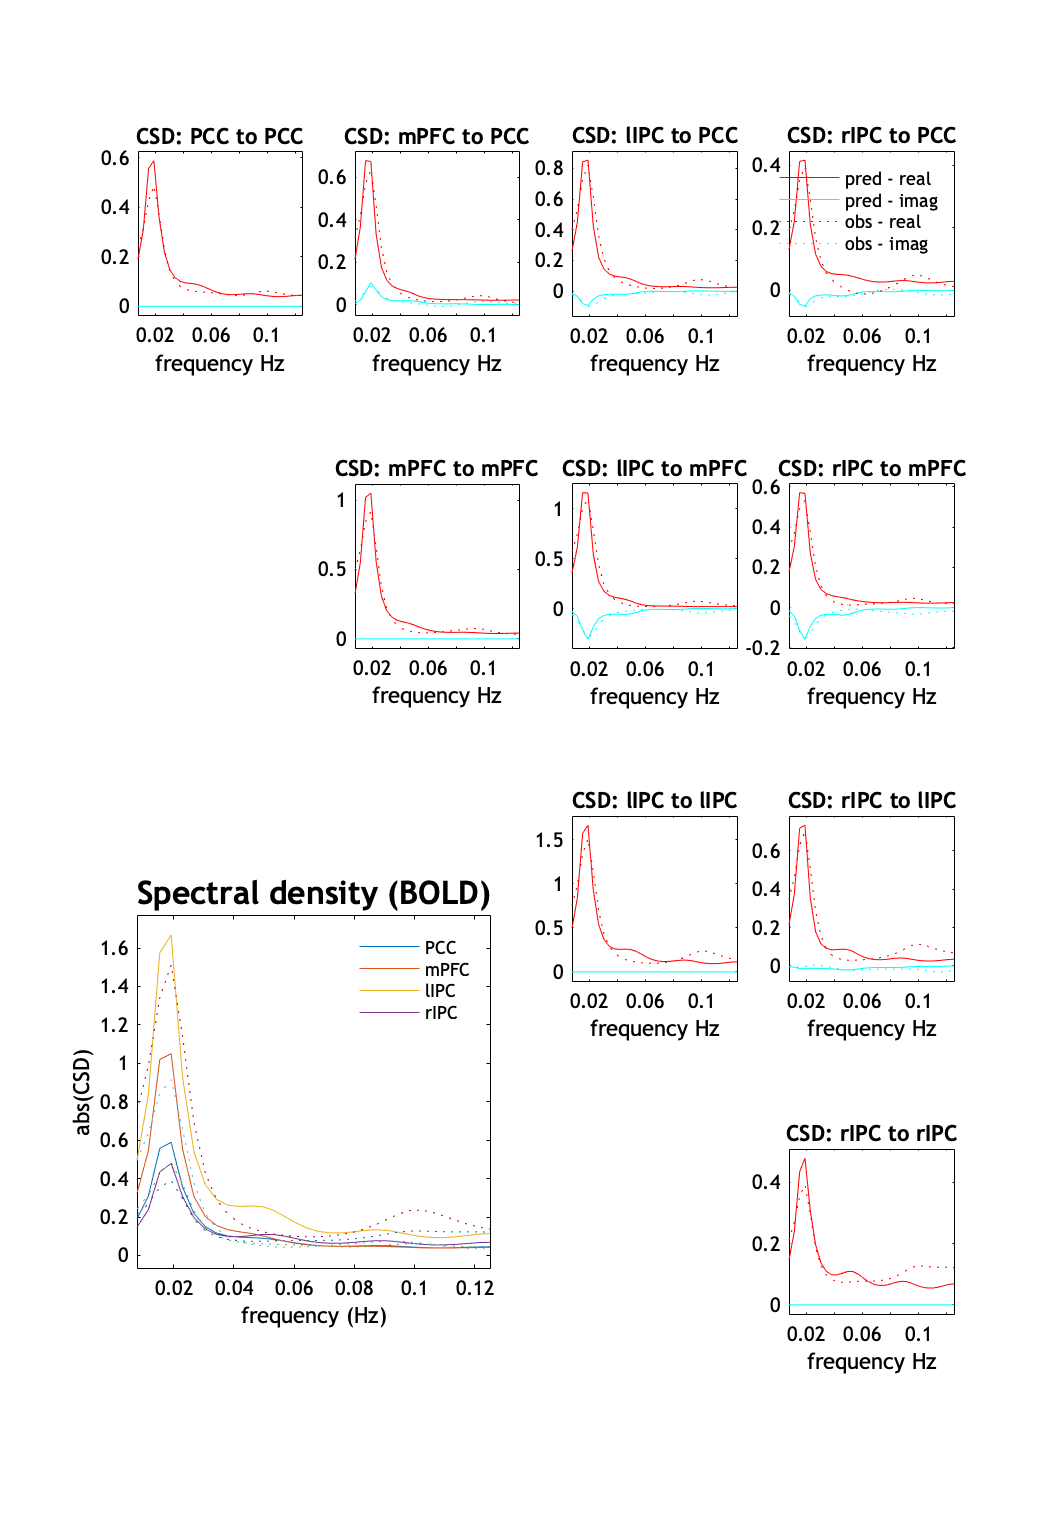

spm_dcm_fmri_csd_results(fullfile(saveDirGLM,'DCM_rsDMN.mat'),'Cross-spectra (BOLD)');

## Plot Coupling of A

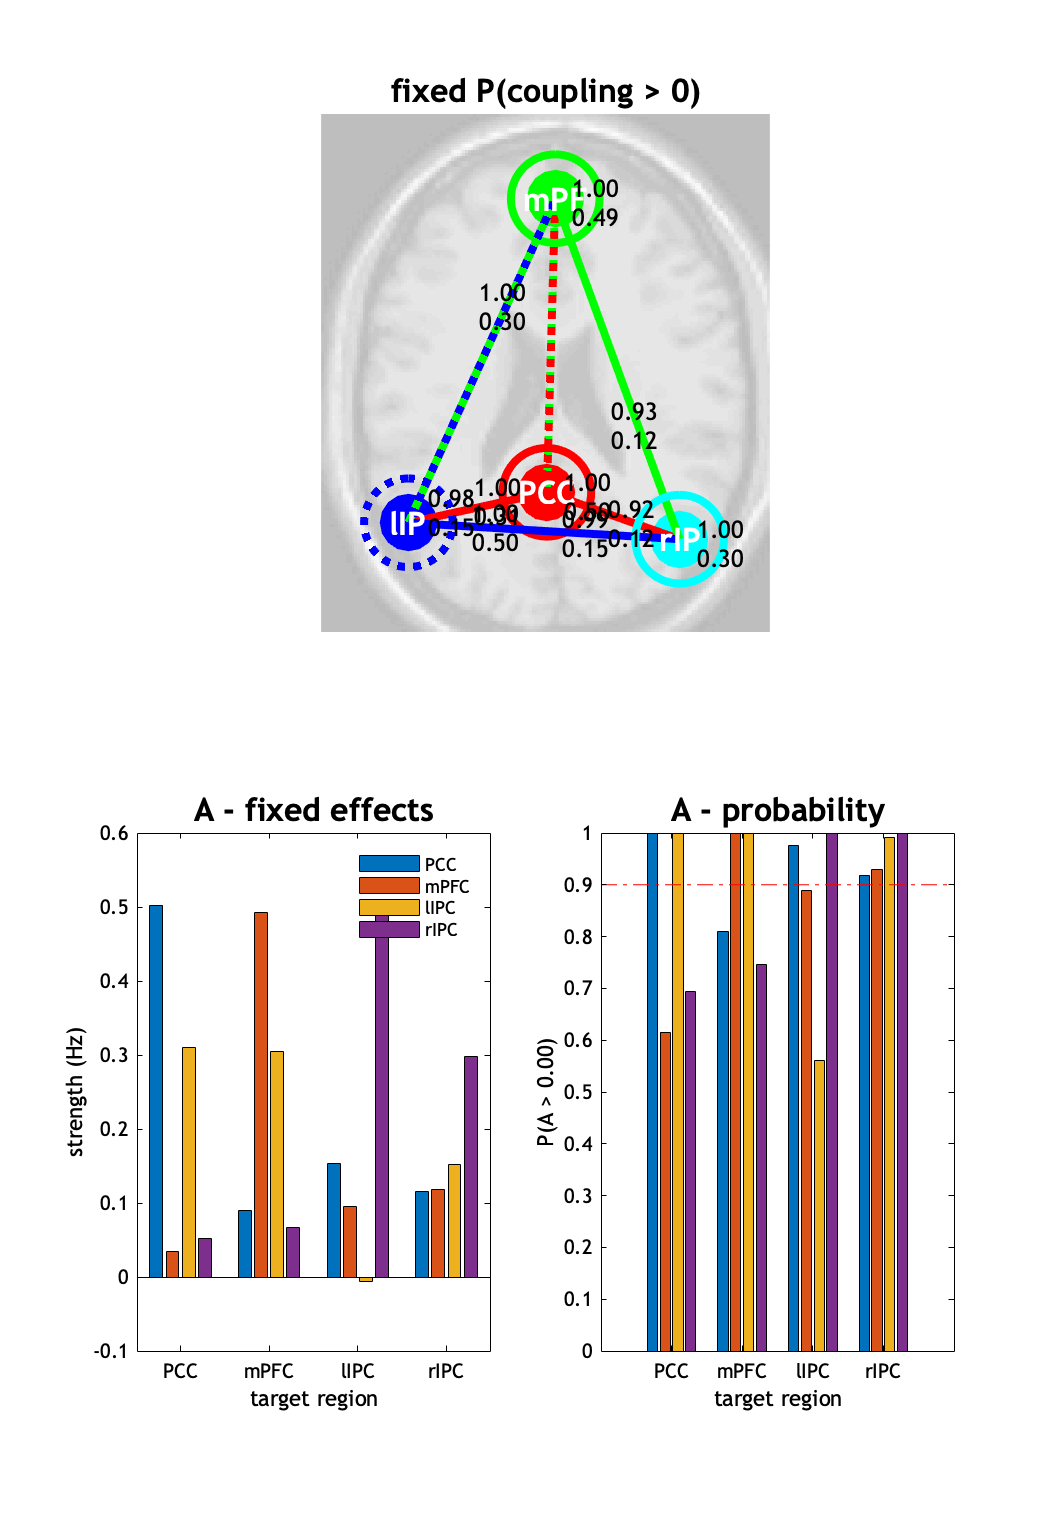

spm_dcm_fmri_csd_results(fullfile(saveDirGLM,'DCM_rsDMN.mat'),'Coupling (A)');

## Functions

function [] = get_VOI(spm_mat_file, mask_file, VOI_name, centre, radius)

% Start batch
clear matlabbatch;
matlabbatch{1}.spm.util.voi.spmmat = {spm_mat_file};
matlabbatch{1}.spm.util.voi.adjust = NaN;
matlabbatch{1}.spm.util.voi.session = 1;
matlabbatch{1}.spm.util.voi.name = VOI_name;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.centre = centre;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.radius = radius;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.move.fixed = 1;
matlabbatch{1}.spm.util.voi.roi{2}.mask.image = {mask_file};
matlabbatch{1}.spm.util.voi.roi{2}.mask.threshold = 0.5;
matlabbatch{1}.spm.util.voi.expression = 'i1&i2';

% Run the batch
spm_jobman('run',matlabbatch);

end